% Datos
x = [16 13 17 14 15];
y = [1.64575 1.00000 1.82843 1.23607 1.44949];

% Reordenar los datos según x para evitar errores en diferencias divididas
[x, idx] = sort(x);
y = y(idx);

n = length(x);
coef = y;  % coeficientes iniciales (f[x0])

% Cálculo de las diferencias divididas
for j = 2:n
    for i = n:-1:j
        coef(i) = (coef(i) - coef(i-1)) / (x(i) - x(i-j+1));
    end
end

% Construcción del polinomio de Newton de forma simbólica
syms X;
P = coef(1);
prod = 1;

for i = 2:n
    prod = prod * (X - x(i-1));
    P = P + coef(i) * prod;
end

% Mostrar el polinomio
disp('Polinomio interpolador de Newton:')

Polinomio interpolador de Newton:


pretty(expand(P))

                 4                      3                          2
   358411470345 X    51012933507182933 X    432202649999475750633 X    58904465033430925714643 X   145617012450809488849357
- ---------------- + -------------------- - ------------------------ + ------------------------- - ------------------------
  4503599627370496    9223372036854775808    2882303761517117440000     28823037615171174400000     14411518807585587200000




% Evaluar en puntos entre 15 y 16
x_interp = 15:0.1:16;
y_interp = double(subs(P, X, x_interp));

% Mostrar tabla de interpolación
fprintf('\nTabla de valores interpolados entre 15 y 16:\n');


Tabla de valores interpolados entre 15 y 16:


fprintf(' x\t\tP(x)\n');

 x		P(x)


fprintf('-----------------------\n');

-----------------------


for i = 1:length(x_interp)
    fprintf('%.1f\t\t%.5f\n', x_interp(i), y_interp(i));
end

15.0		1.44949
15.1		1.46981
15.2		1.48997
15.3		1.50997
15.4		1.52981
15.5		1.54950
15.6		1.56903
15.7		1.58842
15.8		1.60767
15.9		1.62678
16.0		1.64575


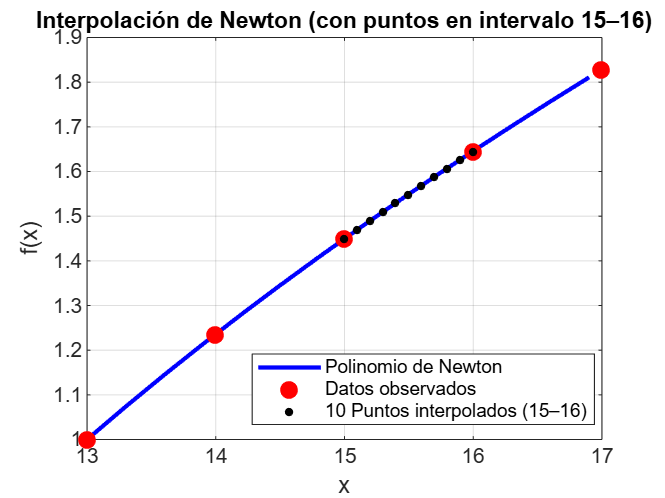


% Gráfica principal
xx = x(1):0.3:x(end);
yy = double(subs(P, X, xx));

figure;
plot(xx, yy, 'b-', 'LineWidth', 2); hold on;
plot(x, y, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');

% Agregar punticos pequeños en el intervalo 15–16
plot(x_interp, y_interp, 'k.', 'MarkerSize', 12);

grid on;
xlabel('x'); ylabel('f(x)');
title('Interpolación de Newton (con puntos en intervalo 15–16)');
legend('Polinomio de Newton', 'Datos observados', '10 Puntos interpolados (15–16)', 'Location', 'Best');